% question b to choose z=3 for looking for residues
z = 3

z = 3

num = [1 z]*32

num =     32    96


den = z * conv([1 4],[1 8])

den =      3    36    96


res = residue(num, den)

res =    13.3333
   -2.6667



clear all;
close all;

% question c to plot step response
% Various coefficients of exponential function
z1 = 2

z1 = 2

num1 = [1 z1]*32

num1 =     32    64


den1 = z1 * conv([1 4],[1 8])

den1 =      2    24    64


G1=tf(num1,den1);

z2 = 5

z2 = 5

num2 = [1 z2]*32

num2 =     32   160


den2 = z2 * conv([1 4],[1 8])

den2 =      5    60   160


G2=tf(num2,den2);

z3 = 20

z3 = 20

num3 = [1 z3]*32

num3 =     32   640


den3 = z3 * conv([1 4],[1 8])

den3 =     20   240   640


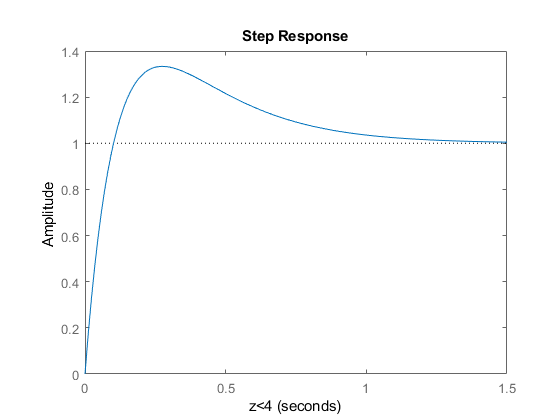

G3=tf(num3,den3);

step(G1);
xlabel('z<4');

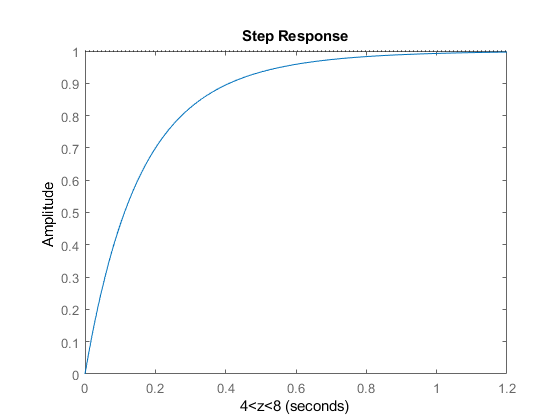


step(G2);
xlabel('4<z<8');

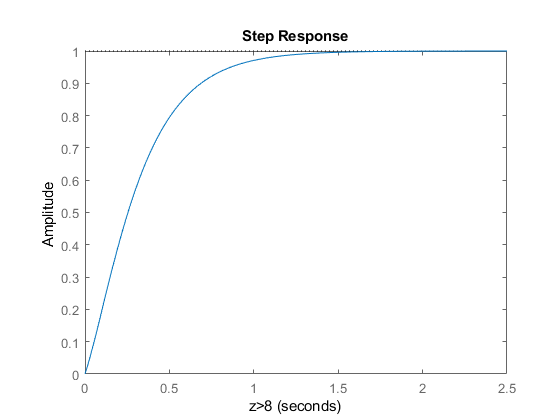


step(G3);
xlabel('z>8');


% question f to display the overshoot
z = 1

z = 1

num = [1 z]*32

num =     32    32


den = z * conv([1 4],[1 8])

den =      1    12    32


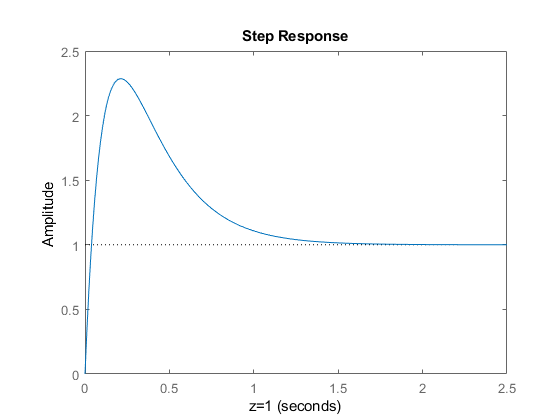

G=tf(num,den);

step(G);
xlabel('z=1');


% question g to investigate the zero in
% right-helf s-plane z<0 
% non-minimum phase behaviour
z = -1

z = -1

num = [1 z]*32

num =     32   -32


den = z * conv([1 4],[1 8])

den =     -1   -12   -32


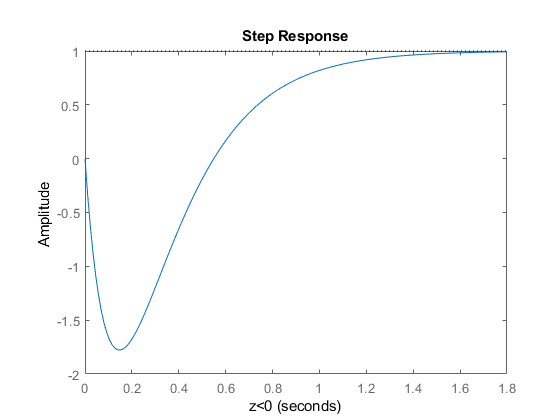

G=tf(num,den);

step(G)
xlabel('z<0');